# `Trial for monovslam object using mobile streamed snaps.`

`This live script is used to test out and get familiar with monovslam object using mbile streamed camera snaps.`

m = mobiledev

m = mobiledev with properties:

                      Device: 'OPPO - CPH1911(ac56)'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
        AvailableMicrophones: {'CPH1911-back' 'CPH1911-bottom' 'TWS-2-BA:98:76:54:43:2F'}
          SelectedMicrophone: 'CPH1911-back'

            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0
           MicrophoneEnabled: 0
Show all properties

cam = camera(m,'back');

numFrames = 30;
imgs = cell(1, numFrames);
tImgs = strings(1, numFrames);
%pause(10);
for i = 1:numFrames
    [imgs{i}, tImgs(i)] = snapshot(cam, 'immediate');
    pause(0.1);
    disp(i);
end
cam = [];

`If needed to store images in a local directory.`

%Create a folder to store the calibration images locally
outputFolder = 'images_SLAM';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end
cd('images_SLAM')

n = numel(imgs);  % Get the number of images in the cell array

for i = 1:n
    img = imgs{i};  % Extract each image from the cell array
    filename = sprintf('image_%d.png', i);  % Create a filename
    imwrite(img, filename);  % Save the image to the current directory
end

`Load mobile camera parameters.`

load("/home/hazem/mobile_calibration_images/mobile_camera_params.mat");
intrinsics = cameraParams.Intrinsics;

`Create VSLAM object.`

myVslam = monovslam(intrinsics, TrackFeatureRange=[15,800])

myVslam =   monovslam with properties:

              Intrinsics: [1×1 cameraIntrinsics]
             ScaleFactor: 1.2000
               NumLevels: 8
            MaxNumPoints: 1000
           SkipMaxFrames: 20
       TrackFeatureRange: [15 800]
    LoopClosureThreshold: 60
                 Verbose: 0


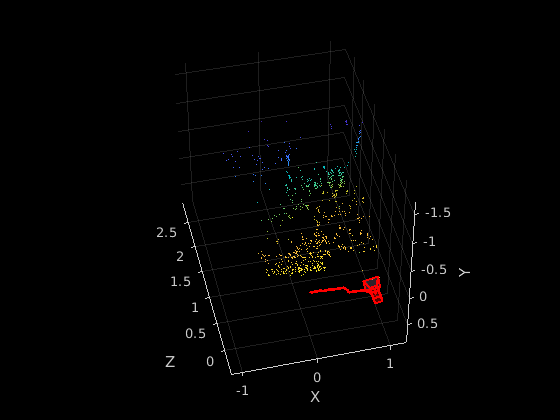

for i = 1:numFrames
    addFrame(myVslam,imgs{i})

    if hasNewKeyFrame(myVslam)
        % Display 3-D map points and camera trajectory
        plot(myVslam);
    end

    %%Get current status of system
    %status = checkStatus(myVslam);
    %disp(status);
end 

xyzPoints = mapPoints(myVslam);
[camPoses,addedFramesIdx] = poses(myVslam);